# Projekt zaliczeniowy - przetwarzenie danych w pakiecie MatLab

***Amelia Madej***

***Informatyka i Ekonometria I rok, stacjonarnie***

Celem niniejszego projektu jest obróbka danych dotyczących wyników na egzaminach uczniów. Wykorzystany zbiór danych zawiera informacje o różnych czynnikach, takich jak płeć, grupa etniczna, wykształcenie rodzica, przygotowanie do testu, stan cywilny rodzica, uprawianie sportu, czy osoba to pierwsze dziecko (1 - tak, 0 - nie), liczba rodzeństwa, liczba godzin nauki tygodniowo oraz wyniki z testów z czystania, pisania i matematyki.

## 1. Załadowanie danych

fname = "schoolData.xlsx";
opts = detectImportOptions(fname);

%podgląd danych przed załadowaniem
preview(fname, opts);
% Wczytanie danych z pliku Excel do tabeli
school = readtable(fname, opts);

## 2. Usuwanie, przenoszenie kolumn, zmiana nazw i łączenie kategorii

% usunięcie kolumn
school = removevars(school, ["Var2", "LunchType", "TransportMeans"]);
% Przeniesienie kolumny "Date" przed kolumnę "Gender"
school = movevars(school, "Date", "Before", "Gender");

% Zmiana nazw kolumn
school.Properties.VariableNames = ...
{'ID', 'Data', 'Plec', 'GrupaEtniczna', 'WyksztalcenieRodzica', 'Przygotowanie', 'StanCywilnyRodzica', 'UprawiaSport', 'PierwszeDziecko', 'LiczbaRodzenstwa', 'LiczbaGodzinNaukiTyg', 'CzytanieWynik', 'PisanieWynik', 'MatematykaWynik'};


oldcats = {'single', 'divorced'};
% Konwersja na zmienną kategoryczną
school.StanCywilnyRodzica = categorical(school.StanCywilnyRodzica);
% Połączenie kategorii
school.StanCywilnyRodzica = mergecats(school.StanCywilnyRodzica, oldcats);

% Konwersja na zmienne kategoryczne
school.Plec = categorical(school.Plec);
school.GrupaEtniczna = categorical(school.GrupaEtniczna);
school.WyksztalcenieRodzica = categorical(school.WyksztalcenieRodzica);
school.Przygotowanie = categorical(school.Przygotowanie);
school.UprawiaSport = categorical(school.UprawiaSport);


%school.Properties;
%head(school);
%summary(school);

% zamiana liczby podanej jako napis na format double
school.LiczbaGodzinNaukiTyg = str2double(school.LiczbaGodzinNaukiTyg);


## 3. Dodanie nowych kolumn

% Obliczenie liczby punktów dla każdego ucznia
liczbaPunktow = sum([school.CzytanieWynik, school.PisanieWynik, school.MatematykaWynik], 2);
% Dodanie kolumny "LiczbaPunktow" do tabeli "school"
school.LiczbaPunktow = liczbaPunktow;


sum(isoutlier(school.LiczbaPunktow));

maxpkt = 300;
% Obliczenie wyniku procentowego na podstawie liczby punktów
school.WynikProc = round((liczbaPunktow/maxpkt)*100, 2);

## 4. Wykorzystanie struktury timetable

% Konwersja tabeli "school" na czasową tabelę "schoolt"
schoolt = table2timetable(school);

% Wybór wybranych kolumn z tabeli "schoolt" do analizy
schooltvalues = schoolt(:, ["LiczbaGodzinNaukiTyg", "LiczbaRodzenstwa", "CzytanieWynik", "PisanieWynik", "MatematykaWynik"]);
% Obliczenie średnich wartości dla wybranych kolumn w "schooltvalues" na podstawie miesięcy
schoolt_meanvalues = retime(schooltvalues, "monthly", "mean");

TR = timerange("2020-01-01", "2020-12-30");
% Wyświetlenie danych pochodzących tylko z 2020 roku
school2020t = schoolt(TR, :);


## 5. Wartości brakujące

%liczba brakow przed normalizacja
sum(ismissing(school));
mvp = {NaN, "", '', "NA", NaT, '<undefined>', 'unknown'};
school = standardizeMissing(school, mvp);

% Określenie logicznego wektora "brakujace" wskazującego na występowanie braków danych w kolumnach "Data" i "MatematykaWynik"
brakujace = ismissing(school.Data) | ismissing(school.MatematykaWynik);

%liczba brakow po normalizacji
s1 = sum(ismissing(school));
fprintf("Liczba wszystkich brakow to %d", sum(s1));

Liczba wszystkich brakow to 9845

% Uzupełnienie brakujących wartości w kolumnach
school.GrupaEtniczna = fillmissing(school.GrupaEtniczna, "previous");
school.WyksztalcenieRodzica = fillmissing(school.WyksztalcenieRodzica, "nearest");
school.Przygotowanie = fillmissing(school.Przygotowanie, "nearest");
school.StanCywilnyRodzica = fillmissing(school.StanCywilnyRodzica, "nearest");
school.UprawiaSport = fillmissing(school.UprawiaSport, "nearest");
school.PierwszeDziecko = fillmissing(school.PierwszeDziecko, "nearest");
school.LiczbaRodzenstwa = fillmissing(school.LiczbaRodzenstwa, "constant", 3);
school.Data = fillmissing(school.Data, "previous");

% Usunięcie wierszy zawierających braki danych
school = rmmissing(school);

sum(ismissing(school));


## 6. Wartości odstające

% Obliczenie liczby wartości odstających przed normalizacją
sum(isoutlier(school(:, vartype("numeric"))));
ovp = {Inf, "", ''};
school = standardizeMissing(school, ovp);

% Obliczenie liczby wartości odstających po normalizacji
s2 = sum(isoutlier(school(:, vartype("numeric"))));
fprintf("Liczba wszystkich wartosci odstających to %d", sum(s2))

Liczba wszystkich wartosci odstających to 11477

% Uzupełnienie/usunięcie wartości odstających
school.LiczbaRodzenstwa = filloutliers(school.LiczbaRodzenstwa, "nearest");
school.CzytanieWynik = filloutliers(school.CzytanieWynik, "next");
school = rmoutliers(school, 'DataVariables', ["PisanieWynik", "MatematykaWynik", "LiczbaPunktow", "WynikProc"]);

% Obliczenie liczby wartości odstających po uzupełnieniu
sum(isoutlier(school(:, vartype("numeric"))));

head(school);

    ID       Data         Plec     GrupaEtniczna    WyksztalcenieRodzica    Przygotowanie    StanCywilnyRodzica    UprawiaSport    PierwszeDziecko    LiczbaRodzenstwa    LiczbaGodzinNaukiTyg    CzytanieWynik    PisanieWynik    MatematykaWynik    LiczbaPunktow    WynikProc
    __    ___________    ______    _____________    ____________________    _____________    __________________    ____________    _______________    ________________    ____________________    _____________    ____________    

## 7. Wykresy

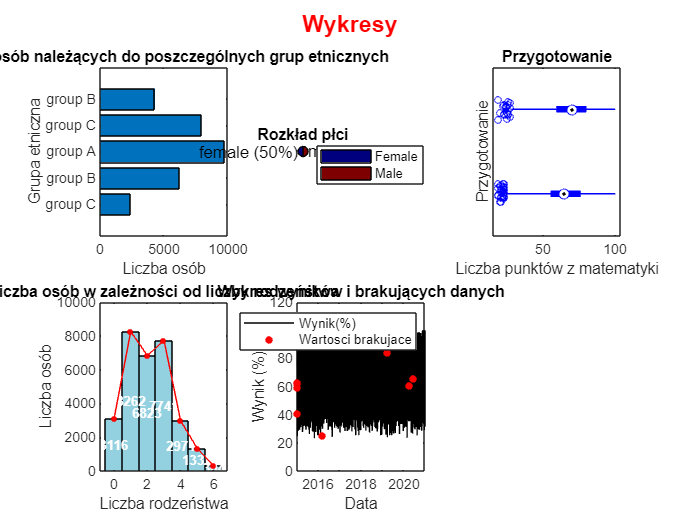

f1 = figure;

% Obliczenie liczby osób należących do poszczególnych grup etnicznych
LiczbaOsob = grpstats(school.ID, school.GrupaEtniczna,"numel");

% 1. Wykres słupkowy przedstawiający liczbę osób w poszczególnych grupach etnicznych
subplot(2, 3, 1);
b1 = barh(LiczbaOsob);
title('Liczba osób należących do poszczególnych grup etnicznych');
ylabel('Grupa etniczna');
yticklabels(school.GrupaEtniczna);
xlabel('Liczba osób');

% 2. Wykres kołowy przedstawiający rozkład płci
subplot(2, 3, 2);
pie(school.Plec);
title('Rozkład płci');
% Kolorowanie sekcji
categories(school.Plec);
colormap(jet(numel(school.Plec)));
etykiety = {"Female", "Male"};
legend(etykiety, 'Location', 'northeastoutside');


% 3. Wykres pudełkowy przedstawiający rozkład liczby punktów w zależności od przygotowania
subplot(2, 3, 3);
boxplot(school.MatematykaWynik, school.Przygotowanie, 'Orientation', 'horizontal', 'PlotStyle', 'compact');
title('Przygotowanie');
xlabel('Liczba punktów z matematyki');
ylabel('Przygotowanie');
categories(school.Przygotowanie);


% 4. Histogram przedstawiający liczbę osób w zależności od liczby rodzeństwa
subplot(2, 3, 4);
h1 = histogram(school.LiczbaRodzenstwa, "FaceColor", [0.3, 0.7, 0.8]);
% Obliczenie średnich wartości dla przedziałów histogramu
x1 = mean([h1.BinEdges(1:end-1); h1.BinEdges(2:end)]);
% Wyświetlenie liczb osób na wykresie
text(x1, h1.Values/2, string(h1.Values), ...
    'Color', [1 1 1], 'FontSize', 8, 'FontWeight', 'bold', ...
    'HorizontalAlignment', 'center');
% Dodanie dodatkowych punktów na wykresie
hold on
p1 = plot(x1, h1.Values);
p1.Color = [1 0 0];
p1.Marker = "o";
p1.MarkerFaceColor = [1 0 0];
p1.MarkerSize = 3;
hold off

title('Liczba osób w zależności od liczby rodzeństwa');
xlabel('Liczba rodzeństwa');
ylabel('Liczba osób');


% 5. Wykres zależności wyników od daty, uwzględniający również brakujące dane
subplot(2, 3, 5);
p1 = plot(school.Data, school.WynikProc, "Color", [0 0 0]);
hold on
p2 = plot(school.Data(brakujace), school.MatematykaWynik(brakujace), "o", "Color", [1 0 0], "MarkerFaceColor", [1 0 0], "MarkerSize", 4);
hold off
ylim([0, 120]);
title('Wykres wyników i brakujących danych');
legend('Wynik(%)', 'Wartosci brakujace', 'FontSize', 8);
xlabel('Data');
ylabel('Wynik (%)');

sgtitle('Wykresy', 'Color', [1 0 0], "FontWeight", "bold");
% zapisanie wykresów do pliku
saveas(f1, "Wykresy.png");

## 8. Normalizacja danych

%% Normalizacja danych (danych kategorycznych nie powinno się normalizować) - zamieniamy je na indeksy

schoolNum = string(school(:, vartype("numeric")).Properties.VariableNames);
% for num = schoolNum
%     disp(num);
% end

schoolCat = string(school(:, vartype("categorical")).Properties.VariableNames);
% for cat = schoolCat
%     disp(cat);
% end


% zamiana na indeksy
for idx = schoolCat
    school.(idx) = grp2idx(school.(idx));
end
 
% normalizacja danych liczbowych
normalized_school = normalize(school(:, ["LiczbaRodzenstwa", "LiczbaGodzinNaukiTyg", "CzytanieWynik", "PisanieWynik", "MatematykaWynik", "LiczbaPunktow"]), "range");

## 9. Zapisanie do pliku .mat

save("school.mat");